# ME 405 Lab 0x06 Observer Tuning and Discretization Example

Author: Charlie Refvem

Modified: 2/26/26

Description: The purpose of this script is to develop a discretized model of a state estimator / state observer to implement in firmware with Micropython. That is, this script will go from the $A$, $B$, $C$, and $D$ matrices making up the open-loop system dynamics all the way through the discretized observer matrices $A_D$, $B_D$, $C_D$, and $D_D$ needed to implement the model in realtime on hardware. 

## Model Parameters

The following parameters are required to build the matrices defining the open-loop model. These parameters must be validated before you trust the output from this script. That is, you must ensure that not only the values are correct but that the correct units are implemented.

tau = 0.04;                          % time constant  [ s ]
r   = 35;                            % wheel radius   [ mm ]
w   = 141;                           % chasis width   [ mm ]
Km = 150 * 2 * pi / (4.5 * 60);      % motor constant [ rad/V-s ]

## Open-loop Romi Dynamics

The matrices defined here should, in theory, come straight from HW 0x03, perhaps with a small amount of modification. Double check that these match your notes as some students have sequenced their variables differently. It's also possible that you may need to convert your state equations to matrix form since the ones in HW 0x03 were in vector form meant for nonlinear equations.

% X = [    s
%         psi
%       omega_L
%       omega_R ]

% U = [  U_L
%        U_R  ]

% Y = [   s_L
%         s_R
%         psi
%       psi_dot ]

A_D = [ 0   0  r/2    r/2   
      0   0 -r/w    r/w   
      0   0 -1/tau  0    
      0   0  0     -1/tau];

B_D = [ 0        0
      0        0      
      Km/tau   0
      0        Km/tau ];

C_D = [ 1    -w/2  0    0    
      1     w/2  0    0    
      0     1    0    0    
      0     0   -r/w  r/w  ];

D_D = [ 0    0 
      0    0 
      0    0 
      0    0 ];

## Controllability and Observability Check

To double-check that the system is both controllable and observable we can examine the rank of the controllability and observability matrices.

display(rank(ctrb(A_D,B_D)))

     4



display(rank(obsv(A_D,C_D)))

     4



## Tuning Criteria for Observer Design

The following parameters, $t_s$, the settling time, and $M_P$, the maximum overshoot, will be used to determine desirable second-order characteristics to use for pole placement.

ts   = 0.25; % Settling time [s]
Mp   = 0.05; % Maximum overshoot (as a decimal value 0 to 1)

These characteristics in the time domain can be used to determine the requisite damping ratio, $\zeta$, and natural frequency, $\omega_n$, for a second-order system to achieve these characteristics.

zeta = sqrt(log(Mp)^2/(pi^2+log(Mp)^2))

zeta = 0.6901

wn   = 4/(zeta*ts)

wn = 23.1848

The poles will be selected using the natural frequency and damping ratio for the proposed second-order system. For the second order poles to dominate the system response, the remaining poles must be significantly faster than the second order poles. Here, they are selected to be at least 10 times faster than the natural frequency for the second order system.

P = [ -10*wn
      -11*wn
      -wn*(zeta+sqrt(zeta^2-1))
      -wn*(zeta-sqrt(zeta^2-1)) ]

P = 1.0e+02 *

  -2.3185 + 0.0000i
  -2.5503 + 0.0000i
  -0.1600 - 0.1678i
  -0.1600 + 0.1678i


## Observer Design by Pole Placement

The observer poles will be placed using MATLAB's built in `place()` function. As mentioned in lecture and in the lab assignment on Canvas, the poles must be placed using $A_O^T = A^T - C^T L^T$ to match the format expected by standard pole placement techniques. See the documentation for `place()` if you would like to understand better.

L = place(A_D', C_D', P)'

L =     3.5000    3.5000    0.0000   -0.0000
   -1.8086    1.8086    0.0257    1.0000
    5.1791    5.1791    0.0000 -416.6514
    5.1791    5.1791    0.0000  416.6514


Once the gain matrix is determined, we can use it to build the continuous time matrices for the closed-loop observer design.

A_O = A_D-L*C_D;
B_O = [B_D-L*D_D, L];
C_O = C_D;
D_O = [D_D zeros(size(C_O,1))];

Finally, the system can be discretized utilizing a sample time, $T_S$, (not to be confused with the settling time used above, $t_s$). Make sure that this sampling time matches the task period that you intend to use in your MCU firmware.

Ts = 0.02; % Sample time [s]
sys_D = c2d(ss(A_O, B_O, C_O, D_O),Ts); % Perform continuous to discrete conversion
sys_D.StateName = ["s","\psi","\Omega_L","\Omega_R"];
sys_D.OutputName = ["s_L","s_R","\psi","d\psi/dt"];

The final step is to extract the new matrices from the output of the continuous to discrete conversion. These are the matrices that need to be transferred to the Micropython firmware to use in real time.

A_D = single(sys_D.A)

A_D = 4×4 single matrix
    0.8139    0.0000    0.2494    0.2494
    0.0000    0.0061    0.0000    0.0000
   -0.1476   -0.0000    0.2835    0.2738
   -0.1476   -0.0000    0.2738    0.2835


B_D = single(sys_D.B)

B_D = 4×6 single matrix
    0.2453    0.2453    0.0930    0.0930    0.0000   -0.0000
    0.0000    0.0000   -0.0070    0.0070    0.0001    0.0039
    0.8573    0.4845    0.0738    0.0738    0.0000   -1.7797
    0.4845    0.8573    0.0738    0.0738    0.0000    1.7797


C_D = single(sys_D.C)

C_D = 4×4 single matrix
    1.0000  -70.5000         0         0
    1.0000   70.5000         0         0
         0    1.0000         0         0
         0         0   -0.2482    0.2482


D_D = single(sys_D.D)

D_D = 4×6 single matrix
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


## Check System Performance

Just as a rudimentary check, we can simulate the initial condition response for the system after tuning and discretization. In the example below, the system starts with an initial state estimate that is off by 100 mm in the displacement parameters; that is, you can imagine the initial conditions as the observer thinking the robot has traveled 100 mm forward when in reality the true state of the system has not traveled anywhere.

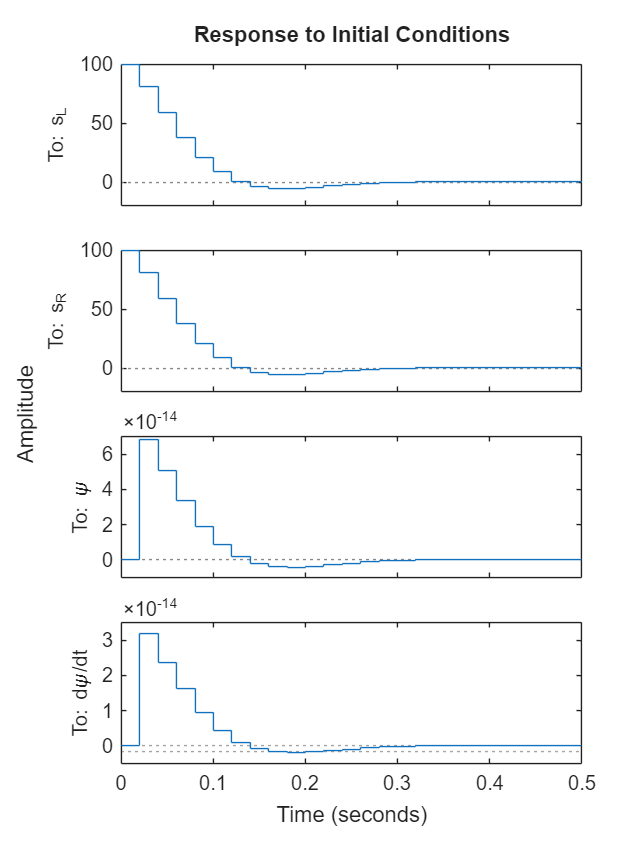

f=figure(1);
f.Position([3 4]) = [600 800];
initial(sys_D,[100;0;0;0])